# Datas

### Flight Conditions

format default
H = 3048

H = 3048

r = 0.905

r = 0.9050

U0 = 121.5  

U0 = 121.5000

M = 0.9

M = 0.9000

theta0 = 1.5

theta0 = 1.5000

g = 9.81

g = 9.8100

### Geometric data

S = 87.8

S = 87.8000

b = 29.3

b = 29.3000

A = 9.777

A = 9.7770

e = 0.86

e = 0.8600

c = 3.078

c = 3.0780

### Inertial data

m = 18143,7

m = 18143

ans = 7

Ixx = 370138,3

Ixx = 370138

ans = 3

Iyy = 291500,6

Iyy = 291500

ans = 6

Izz = 606050,6

Izz = 606050

ans = 6

Ixz = 0

Ixz = 0

### Steady state conditions

CL0 = 0.3 

CL0 = 0.3000

CD0 = 0.036

CD0 = 0.0360

### Longitudinal Aerodynamic derivatives

CDu = 0

CDu = 0

CDalpha = 0.67

CDalpha = 0.6700

CLu = 0

CLu = 0

CLalpha = 5.24

CLalpha = 5.2400

CLalphadot = 1.33

CLalphadot = 1.3300

CLq = 7.83

CLq = 7.8300

Cmu = 0

Cmu = 0

Cmalpha = -0.78

Cmalpha = -0.7800

Cmalphadot = -6.05

Cmalphadot = -6.0500

Cmq = -35.6

Cmq = -35.6000


CDdelta_e = 0

CDdelta_e = 0

CLdelta_e = 0.465

CLdelta_e = 0.4650

Cmdelta_e = -2.12

Cmdelta_e = -2.1200

CDdelta_T = 0

CDdelta_T = 0

CLdelta_T = 0

CLdelta_T = 0

Cmdelta_T = 0

Cmdelta_T = 0

### Lateral Aerodynamic derivatives

Cybeta = -0.362

Cybeta = -0.3620

Cyp = 0

Cyp = 0

Cyr = 0

Cyr = 0

Clbeta = -0.125

Clbeta = -0.1250

Clp = -0.53

Clp = -0.5300

Clr = 0.113

Clr = 0.1130

Cnbeta = 0.101

Cnbeta = 0.1010

Cnp = -0.037

Cnp = -0.0370

Cnr = -0.171

Cnr = -0.1710


Cydelta_r = 0.233

Cydelta_r = 0.2330

Cldelta_r = -0.024

Cldelta_r = -0.0240

Cndelta_r = 0.107

Cndelta_r = 0.1070

Cydelta_a = 0

Cydelta_a = 0

Cldelta_a = 0.2

Cldelta_a = 0.2000

Cndelta_a = 0

Cndelta_a = 0

# I - Longitidunal Dynamic Stability of Airplane

### 1) Aircraft Matrix coefficients

q_bar = 0.5*r*U0^2

q_bar = 6.6799e+03

Xu = -(2*CD0+CDu)*(q_bar*S)/(m*U0)

Xu = -0.0192

Zu = -(2*CL0+CLu)*(q_bar*S)/(m*U0)

Zu = -0.1596

Mu = Cmu*(q_bar*S*c)/(Iyy*U0)

Mu = 0

Xw = (CL0*(1-(2/(pi*e*A)*CLalpha))*(q_bar*S)/(m*U0))

Xw = 0.0482

Zw = -(CD0+CLalpha)*(q_bar*S)/(m*U0)

Zw = -1.4037

Mw = Cmalpha*(q_bar*S*c)/(Iyy*U0)

Mw = -0.0398

Zwdot = (CD0+CLalphadot)*(q_bar*S*c)/(2*m*U0^2)

Zwdot = 0.0046

Mwdot = Cmalphadot*(q_bar*S*c^2)/(2*Iyy*U0^2)

Mwdot = -0.0039

Zq = CLq*(q_bar*S*c)/(2*m*U0)

Zq = 3.2061

Mq = Cmq*(q_bar*S*c^2)/(2*Iyy*U0)

Mq = -2.7926

### Aircraft Matrix A 

disp('Aircraft Matrix A =')

Aircraft Matrix A =


A_long = [Xu Xw  0   -g*cos(theta0);
    Zu  Zw  U0  -g*sin(theta0);
    Mu+Zu*Mwdot Mw+Zw*Mwdot Mq+U0*Mwdot 0;
    0   0   1   0]

A_long =    -0.0192    0.0482         0   -0.6939
   -0.1596   -1.4037  121.5000   -9.7854
    0.0006   -0.0343   -3.2672         0
         0         0    1.0000         0


disp(A_long)

   -0.0192    0.0482         0   -0.6939
   -0.1596   -1.4037  121.5000   -9.7854
    0.0006   -0.0343   -3.2672         0
         0         0    1.0000         0



### Control Matrix coefficients 

Xdelta_e = CDdelta_e*(q_bar*S)/(m*U0)

Xdelta_e = 0

Zdelta_e = CLdelta_e*(q_bar*S)/(m*U0)

Zdelta_e = 0.1237

Mdelta_e = Cmdelta_e*(q_bar*S*c)/(Iyy*U0)

Mdelta_e = -0.1081

### Control Matrix B

disp('Control Matrix B=')

Control Matrix B=


B_long = [Xdelta_e  0;
    Zdelta_e 0;
    Mdelta_e+Zdelta_e*Mwdot 0;
    0 0]

B_long =          0         0
    0.1237         0
   -0.1085         0
         0         0


disp(B_long)

         0         0
    0.1237         0
   -0.1085         0
         0         0



### 2) Characteristic equation

disp('Characteristic equation')

Characteristic equation


A_long_eq = poly(A_long)

A_long_eq =     1.0000    4.6901    8.8477   -0.1459   -0.0017


### 3) Eigenvalues

disp('Roots of the equation')

Roots of the equation


A_long_eig = eig(A_long)

A_long_eig =   -2.3532 + 1.8404i
  -2.3532 - 1.8404i
   0.0242 + 0.0000i
  -0.0080 + 0.0000i


### 4) a/ Short period mode

disp('Short period:')

Short period:


omegaSP = sqrt((-2.3532 + 1.8404i) * (-2.3532 - 1.8404i))

omegaSP = 2.9874

xiSP = 0.7877

xiSP = 0.7877

####         Short period matrix approximation

A_SP = [Zw  U0;
    Mw+Zw*Mwdot Mq+U0*Mwdot]

A_SP =    -1.4037  121.5000
   -0.0343   -3.2672



B_SP = [Zdelta_e 0;
    Mdelta_e+Zdelta_e*Mwdot 0]

B_SP =     0.1237         0
   -0.1085         0


####         Characteristic equation

disp('Characteristic equation')

Characteristic equation


A_SP_eq = poly(A_SP)

A_SP_eq =     1.0000    4.6709    8.7505


####         Eigenvalues

disp('Roots of the equation')

Roots of the equation


A_SP_eig = eig(A_SP)

A_SP_eig =   -2.3355 + 1.8155i
  -2.3355 - 1.8155i


### 4) b/ Phugoid period mode

disp('Phugoïd period:')

Phugoïd period:


omegaPH = 0.0917

omegaPH = 0.0917

xiPH = 0.0294

xiPH = 0.0294

####         Phugoid matrix approximation

A_PH = [Xu -g*cos(theta0);
    -Zu/U0 g*cos(theta0)/U0]

A_PH =    -0.0192   -0.6939
    0.0013    0.0057



B_PH = [Xdelta_e 0;
    -Zdelta_e/U0 0]

B_PH =          0         0
   -0.0010         0


####         Characteristic equation

disp('Characteristic equation')

Characteristic equation


A_PH_eq = poly(A_PH)

A_PH_eq =     1.0000    0.0134    0.0008


####         Eigenvalues

disp('Roots of the equation')

Roots of the equation


A_PH_eig = eig(A_PH)

A_PH_eig =   -0.0067 + 0.0275i
  -0.0067 - 0.0275i


### 5) Curves of longitudinal motion

####         5) a/ Axial velocity in function of time

t = 0:0.01:600

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


%Axial velocity in function of time
u = exp(-xiPH*omegaPH*t).*((U0/10)*cos(omegaPH*sqrt(1-xiPH^2)*t)+((10*xiPH*omegaPH)/(omegaPH*sqrt(1-xiPH^2))*sin(omegaPH*sqrt(1-xiPH^2)*t)))

u =    12.1500   12.1499   12.1499   12.1498   12.1497   12.1496   12.1495   12.1493   12.1492   12.1491   12.1489   12.1487   12.1486   12.1484   12.1482   12.1480   12.1478   12.1475   12.1473   12.1471   12.1468   12.1465   12.1463   12.1460   12.1457   12.1454   12.1450   12.1447   12.1444   12.1440   12.1437   12.1433   12.1429   12.1425   12.1421   12.1417   12.1413   12.1409   12.1404   12.1400   12.1395   12.1390   12.1386   12.1381   12.1376   12.1371   12.1365   12.1360   12.1355   12.1349


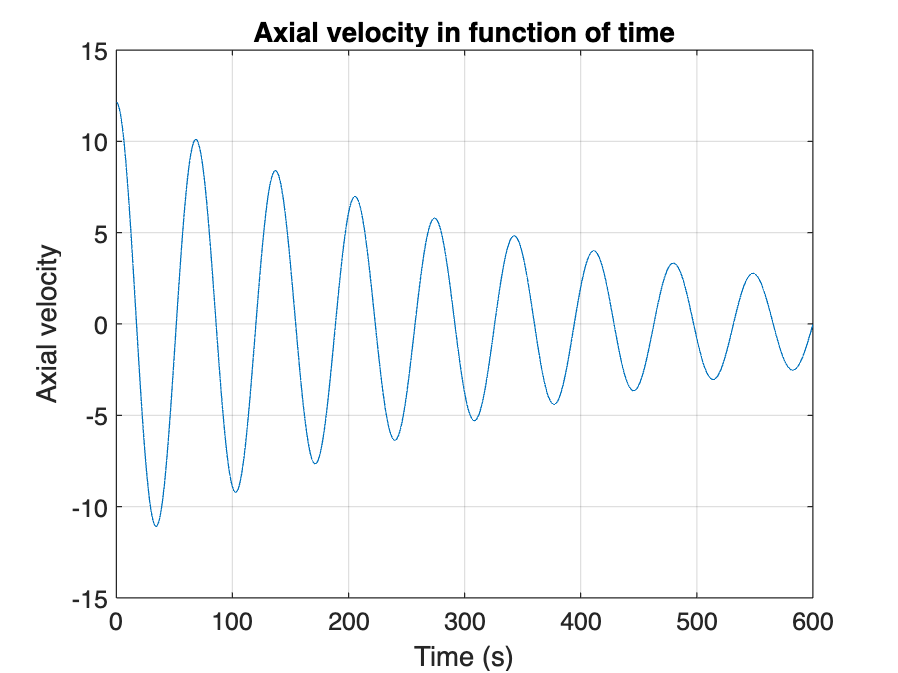


figure
plot(t, u)
title('Axial velocity in function of time')
xlabel('Time (s)')
ylabel('Axial velocity')
grid on

####         5) b/ Angle of attack

t = 0:0.1:20

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


%Angle of attack
omega = exp(-xiSP*omegaSP*t).*((theta0/10)*cos(omegaSP*sqrt(1-xiSP^2)*t)+((10*xiSP*omegaSP)/omegaSP*sqrt(1-xiSP^2)*sin(omegaSP*sqrt(1-xiSP^2)*t)))

omega =     0.1500    0.8184    1.1781    1.3195    1.3146    1.2186    1.0726    0.9056    0.7373    0.5800    0.4409    0.3228    0.2262    0.1499    0.0917    0.0488    0.0186   -0.0016   -0.0141   -0.0209   -0.0237   -0.0237   -0.0221   -0.0195   -0.0165   -0.0135   -0.0106   -0.0081   -0.0059   -0.0042   -0.0028   -0.0017   -0.0009   -0.0004    0.0000    0.0002    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000


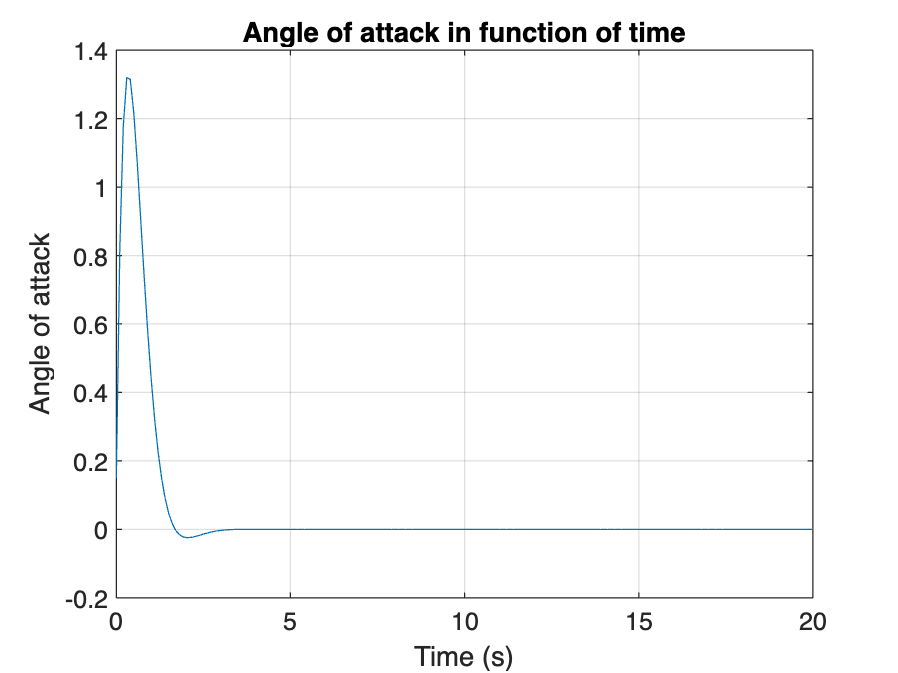


figure
plot(t, omega)
title('Angle of attack in function of time')
xlabel('Time (s)')
ylabel('Angle of attack')
grid on

####         5) c/ Pitch rate

t = 0:0.1:20

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


%Pitch rate
q = exp(-omegaSP*xiSP*t).*(theta0/10*cos(omegaSP*sqrt(1-xiSP^2)*t) + (theta0*omegaSP*xiSP)/(omegaSP*sqrt(1-xiSP^2))*sin(omegaSP*sqrt(1-xiSP^2)*t))

q =     0.1500    0.3939    0.5185    0.5596    0.5458    0.4986    0.4338    0.3628    0.2927    0.2283    0.1719    0.1246    0.0862    0.0561    0.0334    0.0168    0.0053   -0.0023   -0.0069   -0.0092   -0.0101   -0.0099   -0.0091   -0.0079   -0.0066   -0.0054   -0.0042   -0.0032   -0.0023   -0.0016   -0.0010   -0.0006   -0.0003   -0.0001    0.0000    0.0001    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


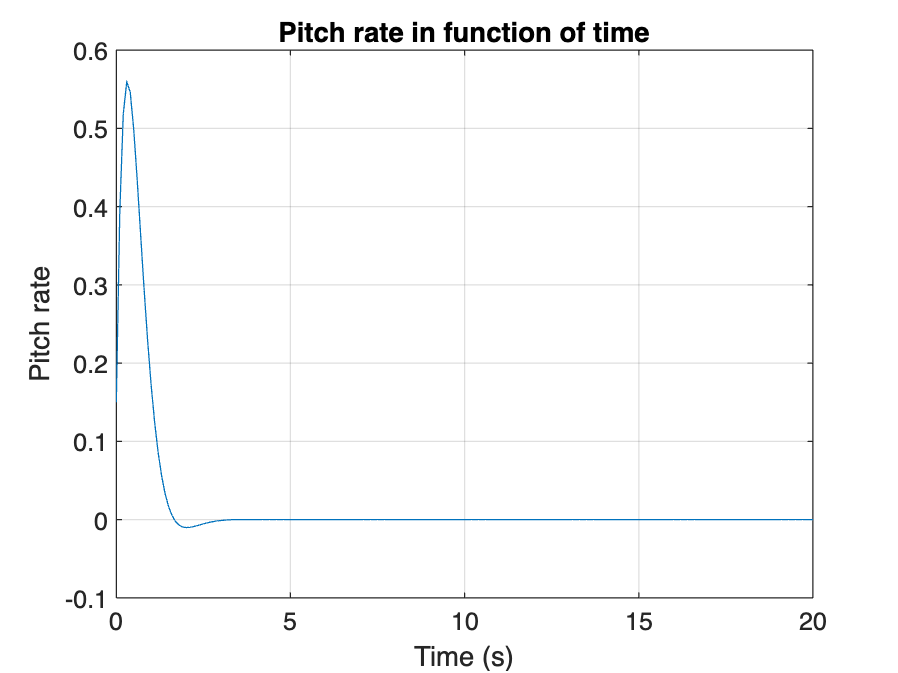


figure
plot(t, q)
title('Pitch rate in function of time')
xlabel('Time (s)')
ylabel('Pitch rate')
grid on

####         5) d/ Pitch angle

t = 0:0.01:700

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


%Pitch angle
theta = exp(-xiPH*omegaPH*t).*((theta0/10)*cos(omegaPH*sqrt(1-xiPH^2)*t)+((theta0*xiPH*omegaPH)/omegaPH*sqrt(1-xiPH^2)*sin(omegaPH*sqrt(1-xiPH^2)*t)))

theta =     0.1500    0.1500    0.1501    0.1501    0.1501    0.1502    0.1502    0.1503    0.1503    0.1503    0.1504    0.1504    0.1504    0.1505    0.1505    0.1505    0.1506    0.1506    0.1506    0.1507    0.1507    0.1507    0.1508    0.1508    0.1508    0.1509    0.1509    0.1509    0.1510    0.1510    0.1510    0.1511    0.1511    0.1511    0.1512    0.1512    0.1512    0.1513    0.1513    0.1513    0.1514    0.1514    0.1514    0.1514    0.1515    0.1515    0.1515    0.1516    0.1516    0.1516


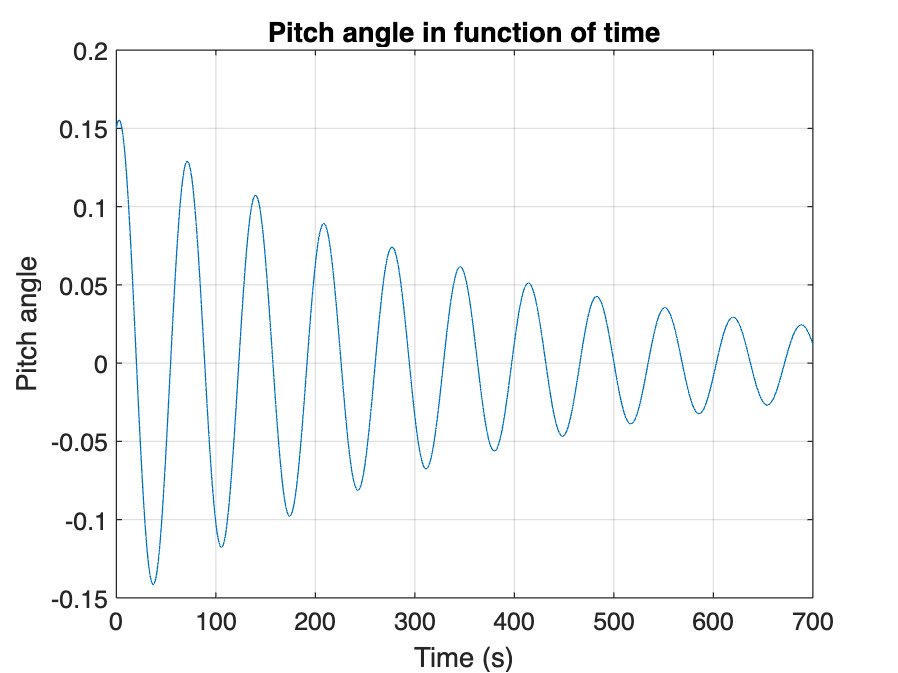


figure
plot(t, theta)
title('Pitch angle in function of time')
xlabel('Time (s)')
ylabel('Pitch angle')
grid on

### 6) Transfert function of each variables

s = sym('s')

$$s = s$$

I1 = eye(2,2)

I1 =      1     0
     0     1


####         Short period

adj_A_SP = vpa(adjoint(s*I1-A_SP))

$$adj\_A\_SP = \left(\begin{array}{cc} s+3.267179980962799490384895761963 & 121.5\\ -0.034273989328092925588098438538509 & s+1.4037347904425949707274412503466 \end{array}\right)$$

det1 = vpa(det(s*I1-A_SP))

$$det1 = s^{2}+4.6709147714053944611123370123096\,s+8.7505439092783472274370212560417$$

M1 = vpa(adj_A_SP*[Zdelta_e; Mdelta_e+Zdelta_e*Mwdot])

$$M1 = \left(\begin{array}{c} 0.12371809657994820019766279983742\,s-12.783503098209948583315467833597\\ -0.1085408426883850002697684544728\,s-0.15660286978751589937448154304605 \end{array}\right)$$

####         Bode Short Period

%w('s')
w = tf(sym2poly(M1(1)), poly(A_SP))


w =
 
    0.1237 s - 12.78
  ---------------------
  s^2 + 4.671 s + 8.751
 
Continuous-time transfer function.
Model Properties


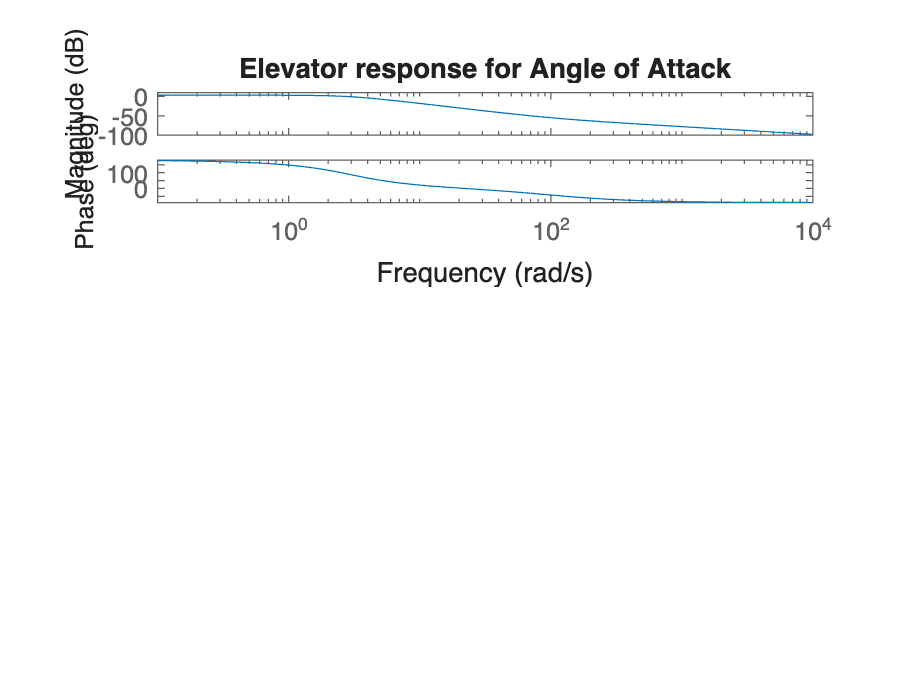



figure('Name', 'Bode Short Period')
subplot(2,1,1)
bode(w)
title('Elevator response for Angle of Attack')

%q(s)
q = tf(sym2poly(M1(2)), poly(A_SP))


q =
 
   -0.1085 s - 0.1566
  ---------------------
  s^2 + 4.671 s + 8.751
 
Continuous-time transfer function.
Model Properties


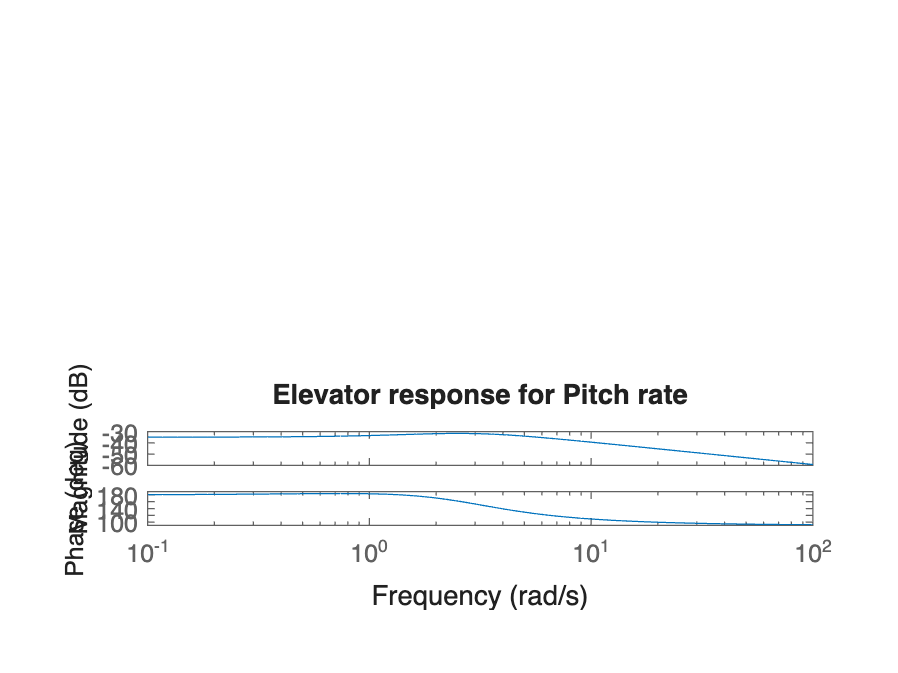


figure('Name', 'Bode Short Period')
subplot(2,1,2)
bode(q)
title('Elevator response for Pitch rate')

####         Phugoid

adj_A_PH = vpa(adjoint(s*I1-A_PH))

$$adj\_A\_PH = \left(\begin{array}{cc} s-0.0057113740605774943742689586656525 & -0.69393194836016558468827497563325\\ 0.0013138786308769221950615291305553 & s+0.019156350438185525131284947519816 \end{array}\right)$$

det2 = vpa(det(s*I1-A_PH))

$$det2 = s^{2}+0.013444976377608030757015988854164\,s+0.00080233327524522430605082400086642$$

M2 = vpa(adj_A_PH*[Xdelta_e; -Zdelta_e/U0])

$$M2 = \left(\begin{array}{c} 0.00070660032763073741917365860013501\\ -0.0010182559389296148583820000865785\,s-0.000019506067601899340910288929630561 \end{array}\right)$$

####         Bode Phugoid

%u(s)
u = tf(sym2poly(M2(1)), poly(A_PH))


u =
 
           0.0007066
  ---------------------------
  s^2 + 0.01344 s + 0.0008023
 
Continuous-time transfer function.
Model Properties


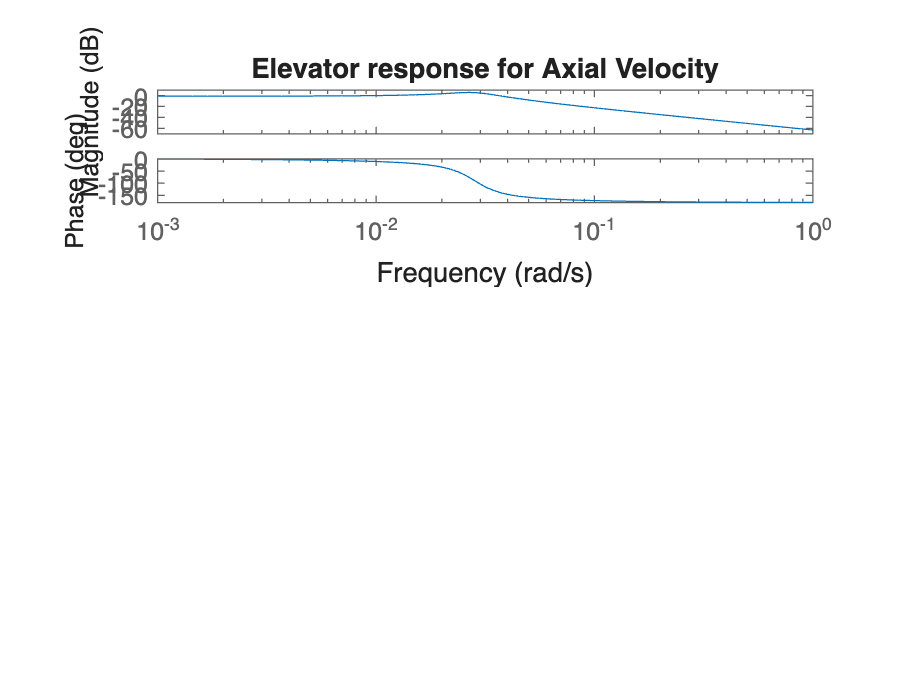


figure('Name', 'Bode Phugoid')
subplot(2,1,1)
bode(u)
title('Elevator response for Axial Velocity')

%theta(s)
theta = tf(sym2poly(M2(2)), poly(A_PH))


theta =
 
    -0.001018 s - 1.951e-05
  ---------------------------
  s^2 + 0.01344 s + 0.0008023
 
Continuous-time transfer function.
Model Properties


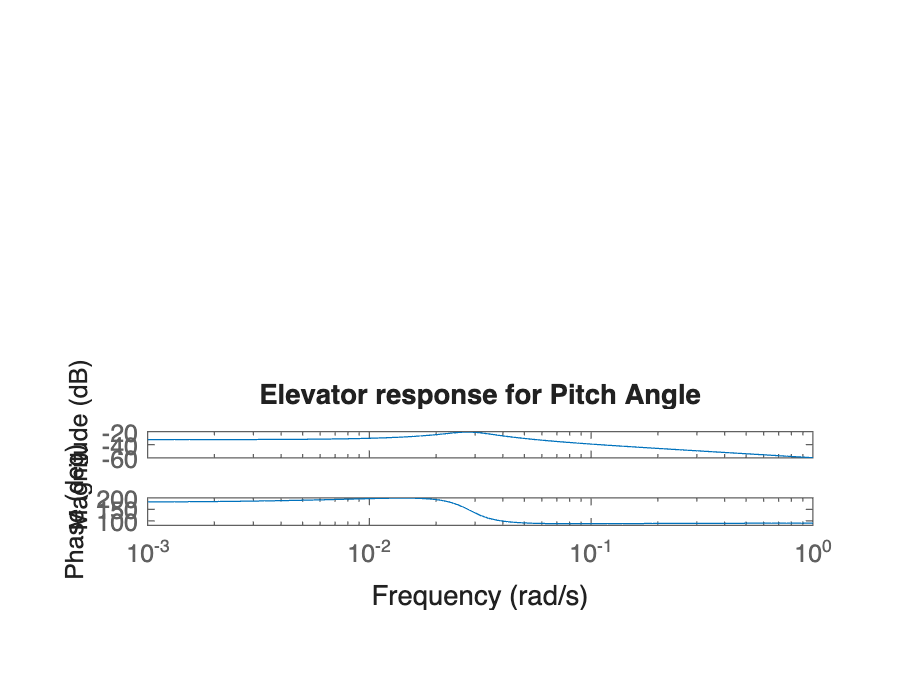


figure('Name', 'Bode Phugoid')
subplot(2,1,2)
bode(theta)
title('Elevator response for Pitch Angle')

# II - Lateral Dynamic Stability of Airplane

### 1) Aircraft Matrix coefficients

Yv = Cybeta*(q_bar*S)/(m*U0)

Yv = -0.0963

Lv = Clbeta*(q_bar*S*b)/(Ixx*U0)

Lv = -0.0478

Nv = Cnbeta*(q_bar*S*b)/(Izz*U0)

Nv = 0.0236

Yp = Cyp*(q_bar*S*b)/(2*m*U0)

Yp = 0

Lp = Clp*(q_bar*S*b^2)/(2*Ixx*U0)

Lp = -2.9669

Np = Cnp*(q_bar*S*b^2)/(2*Izz*U0)

Np = -0.1265

Yr = Cyr*(q_bar*S*b)/(2*m*U0)

Yr = 0

lambda_roll = Clr*(q_bar*S*b^2)/(2*Ixx*U0)

lambda_roll = 0.6326

Nr = Cnr*(q_bar*S*b^2)/(2*Izz*U0)

Nr = -0.5846

### Aircraft Matrix A 

disp('Aircraft Matrix A =')

Aircraft Matrix A =


A_lat = [Yv Yp Yr-U0 g*cos(theta0);
    Lv Lp lambda_roll 0;
    Nv Np Nr 0;
    0 1 0 0]

A_lat =    -0.0963         0 -121.5000    0.6939
   -0.0478   -2.9669    0.6326         0
    0.0236   -0.1265   -0.5846         0
         0    1.0000         0         0


disp(A_lat)

   -0.0963         0 -121.5000    0.6939
   -0.0478   -2.9669    0.6326         0
    0.0236   -0.1265   -0.5846         0
         0    1.0000         0         0



### Control Matrix coefficients

%Rudder Derivatives
Ydelta_r = Cydelta_r*(q_bar*S)/(m*U0)

Ydelta_r = 0.0620

Ldelta_r = Cldelta_r*(q_bar*S*b)/(Ixx*U0)

Ldelta_r = -0.0092

Ndelta_r = Cndelta_r*(q_bar*S*b)/(Izz*U0)

Ndelta_r = 0.0250

%Aileron Derivatives
Ydelta_a = Cydelta_a*(q_bar*S)/(m*U0)

Ydelta_a = 0

Ldelta_a = Cldelta_a*(q_bar*S*b)/(Ixx*U0)

Ldelta_a = 0.0764

Ndelta_a = Cndelta_a*(q_bar*S*b)/(Izz*U0)

Ndelta_a = 0

disp('Control Matrix B=')

Control Matrix B=


B_lat = [Ydelta_r Ydelta_a;
    Ldelta_r Ldelta_a;
    Ndelta_r Ndelta_a;
    0 0]

B_lat =     0.0620         0
   -0.0092    0.0764
    0.0250         0
         0         0


disp(B_lat)

    0.0620         0
   -0.0092    0.0764
    0.0250         0
         0         0



### 2) Characteristic equation

disp('Characteristic equation')

Characteristic equation


A_lat_eq = poly(A_lat)

A_lat_eq =     1.0000    3.6479    5.0205    9.4388    0.0090


### 3) Eigenvalues

disp('Roots of the equation')

Roots of the equation


[eigenvectors, eigenvalues] = eig(A_lat)

eigenvectors =   -0.8344 + 0.0000i   0.9997 + 0.0000i   0.9997 + 0.0000i   0.1325 + 0.0000i
  -0.5230 + 0.0000i  -0.0138 + 0.0057i  -0.0138 - 0.0057i  -0.0009 + 0.0000i
  -0.0191 + 0.0000i   0.0018 - 0.0143i   0.0018 + 0.0143i   0.0056 + 0.0000i
   0.1732 + 0.0000i   0.0045 + 0.0071i   0.0045 - 0.0071i   0.9912 + 0.0000i


eigenvalues =   -3.0200 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.3134 + 1.7394i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.3134 - 1.7394i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0010 + 0.0000i


eig(A_lat)

ans =   -3.0200 + 0.0000i
  -0.3134 + 1.7394i
  -0.3134 - 1.7394i
  -0.0010 + 0.0000i


### 4) Different modes of lateral stability

####         4) a/ Spiral mode

lambda_spiral = eigenvalues(4,4)

lambda_spiral = -9.5730e-04

####         4) b/ Rolling mode

lambda_roll = eigenvalues(3,3)

lambda_roll = -0.3134 - 1.7394i

####         4) c/ Dutch roll mode

lambda_dutch1 = eigenvalues(1,1)

lambda_dutch1 = -3.0200

lambda_dutch2 = eigenvalues(2,2)

lambda_dutch2 = -0.3134 + 1.7394i

### 5/ Curves of lateral motion

omegadutch = 0.0149 

omegadutch = 0.0149

xidutch = 0.926

xidutch = 0.9260

%Rolling mode curve
t = 0:0.001:10

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


f13 = eigenvectors(1,3).*exp(lambda_roll*t)

f13 =    0.9997 + 0.0000i   0.9994 - 0.0017i   0.9991 - 0.0035i   0.9988 - 0.0052i   0.9985 - 0.0069i   0.9981 - 0.0087i   0.9978 - 0.0104i   0.9975 - 0.0121i   0.9971 - 0.0139i   0.9968 - 0.0156i   0.9965 - 0.0173i   0.9961 - 0.0191i   0.9958 - 0.0208i   0.9954 - 0.0225i   0.9951 - 0.0242i   0.9947 - 0.0260i   0.9944 - 0.0277i   0.9940 - 0.0294i   0.9936 - 0.0311i   0.9933 - 0.0328i   0.9929 - 0.0346i   0.9925 - 0.0363i   0.9922 - 0.0380i   0.9918 - 0.0397i   0.9914 - 0.0414i   0.9910 - 0.0431i   0.9906 - 0.0448i   0.9902 - 0.0465i   0.9898 - 0.0482i   0.9894 - 0.0500i   0.9890 - 0.0517i   0.9886 - 0.0534i   0.9882 - 0.0551i   0.9878 - 0.0568i   0.9874 - 0.0585i   0.9870 - 0.0602i   0.9866 - 0.0619i   0.9862 - 0.0636i   0.9858 - 0.0653i   0.9853 - 0.0669i   0.9849 - 0.0686i   0.9845 - 0.0703i   0.9840 - 0.0720i   0.9836 - 0.0737i   0.9832 - 0.0754i   0.9827 - 0.0771i   0.9823 - 0.0788i   0.9818 - 0.0804i   0.9814 - 0.0821i   0.9809 - 0.0838i


f23 = eigenvectors(2,3).*exp(lambda_roll*t)

f23 =   -0.0138 - 0.0057i  -0.0139 - 0.0056i  -0.0139 - 0.0056i  -0.0139 - 0.0056i  -0.0139 - 0.0056i  -0.0139 - 0.0055i  -0.0139 - 0.0055i  -0.0139 - 0.0055i  -0.0139 - 0.0055i  -0.0139 - 0.0054i  -0.0139 - 0.0054i  -0.0139 - 0.0054i  -0.0139 - 0.0054i  -0.0139 - 0.0053i  -0.0139 - 0.0053i  -0.0139 - 0.0053i  -0.0139 - 0.0053i  -0.0139 - 0.0052i  -0.0139 - 0.0052i  -0.0139 - 0.0052i  -0.0139 - 0.0052i  -0.0140 - 0.0051i  -0.0140 - 0.0051i  -0.0140 - 0.0051i  -0.0140 - 0.0051i  -0.0140 - 0.0050i  -0.0140 - 0.0050i  -0.0140 - 0.0050i  -0.0140 - 0.0049i  -0.0140 - 0.0049i  -0.0140 - 0.0049i  -0.0140 - 0.0049i  -0.0140 - 0.0048i  -0.0140 - 0.0048i  -0.0140 - 0.0048i  -0.0140 - 0.0048i  -0.0140 - 0.0047i  -0.0140 - 0.0047i  -0.0140 - 0.0047i  -0.0140 - 0.0047i  -0.0140 - 0.0046i  -0.0140 - 0.0046i  -0.0140 - 0.0046i  -0.0140 - 0.0046i  -0.0140 - 0.0045i  -0.0140 - 0.0045i  -0.0141 - 0.0045i  -0.0141 - 0.0045i  -0.0141 - 0.0044i  -0.0141 - 0.0044i


f33 = eigenvectors(3,3).*exp(lambda_roll*t)

f33 =    0.0018 + 0.0143i   0.0018 + 0.0143i   0.0019 + 0.0143i   0.0019 + 0.0142i   0.0019 + 0.0142i   0.0019 + 0.0142i   0.0020 + 0.0142i   0.0020 + 0.0142i   0.0020 + 0.0142i   0.0020 + 0.0142i   0.0021 + 0.0142i   0.0021 + 0.0142i   0.0021 + 0.0142i   0.0021 + 0.0142i   0.0022 + 0.0142i   0.0022 + 0.0142i   0.0022 + 0.0141i   0.0022 + 0.0141i   0.0022 + 0.0141i   0.0023 + 0.0141i   0.0023 + 0.0141i   0.0023 + 0.0141i   0.0023 + 0.0141i   0.0024 + 0.0141i   0.0024 + 0.0141i   0.0024 + 0.0141i   0.0024 + 0.0141i   0.0025 + 0.0141i   0.0025 + 0.0140i   0.0025 + 0.0140i   0.0025 + 0.0140i   0.0026 + 0.0140i   0.0026 + 0.0140i   0.0026 + 0.0140i   0.0026 + 0.0140i   0.0026 + 0.0140i   0.0027 + 0.0140i   0.0027 + 0.0140i   0.0027 + 0.0140i   0.0027 + 0.0139i   0.0028 + 0.0139i   0.0028 + 0.0139i   0.0028 + 0.0139i   0.0028 + 0.0139i   0.0029 + 0.0139i   0.0029 + 0.0139i   0.0029 + 0.0139i   0.0029 + 0.0139i   0.0030 + 0.0139i   0.0030 + 0.0139i


f43 = eigenvectors(4,3).*exp(lambda_roll*t)

f43 =    0.0045 - 0.0071i   0.0045 - 0.0071i   0.0045 - 0.0072i   0.0045 - 0.0072i   0.0045 - 0.0072i   0.0045 - 0.0072i   0.0045 - 0.0072i   0.0045 - 0.0072i   0.0044 - 0.0072i   0.0044 - 0.0072i   0.0044 - 0.0072i   0.0044 - 0.0072i   0.0044 - 0.0072i   0.0044 - 0.0072i   0.0044 - 0.0072i   0.0043 - 0.0072i   0.0043 - 0.0072i   0.0043 - 0.0072i   0.0043 - 0.0072i   0.0043 - 0.0072i   0.0043 - 0.0072i   0.0043 - 0.0073i   0.0042 - 0.0073i   0.0042 - 0.0073i   0.0042 - 0.0073i   0.0042 - 0.0073i   0.0042 - 0.0073i   0.0042 - 0.0073i   0.0042 - 0.0073i   0.0041 - 0.0073i   0.0041 - 0.0073i   0.0041 - 0.0073i   0.0041 - 0.0073i   0.0041 - 0.0073i   0.0041 - 0.0073i   0.0041 - 0.0073i   0.0040 - 0.0073i   0.0040 - 0.0073i   0.0040 - 0.0073i   0.0040 - 0.0073i   0.0040 - 0.0073i   0.0040 - 0.0074i   0.0040 - 0.0074i   0.0039 - 0.0074i   0.0039 - 0.0074i   0.0039 - 0.0074i   0.0039 - 0.0074i   0.0039 - 0.0074i   0.0039 - 0.0074i   0.0039 - 0.0074i



figure
plot(t, f13, t, f23, t, f33, t, f43)

title('Rolling mode')
xlabel('Time (s)')
legend('Side velocity', 'Roll rate', 'Yaw rate', 'Side angle')
grid on

%Spiral mode curve
t = 0:0.1:700

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


f12 = eigenvectors(1,4).*exp(lambda_spiral*t);
f22 = eigenvectors(2,4).*exp(lambda_spiral*t);
f32 = eigenvectors(3,4).*exp(lambda_spiral*t);
f42 = eigenvectors(4,4).*exp(lambda_spiral*t);

figure
plot(t, f12, t, f22, t, f32, t, f42)
title('Spiral mode')
xlabel('Time (s)')
legend('Side Velocity', 'Roll Rate', 'Yaw Rate', 'Side angle');
grid on

%Dutch Roll mode curve
t = 0:0.01:100

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f11 = real(eigenvectors(1,1)).*exp(real(lambda_dutch1)*t).*(cos(omegadutch*t)+xidutch*sin(omegadutch*t))

f11 =    -0.8344   -0.8096   -0.7857   -0.7624   -0.7398   -0.7179   -0.6967   -0.6760   -0.6560   -0.6366   -0.6177   -0.5994   -0.5817   -0.5644   -0.5477   -0.5315   -0.5158   -0.5005   -0.4857   -0.4713   -0.4573   -0.4438   -0.4306   -0.4179   -0.4055   -0.3935   -0.3818   -0.3705   -0.3596   -0.3489   -0.3386   -0.3286   -0.3188   -0.3094   -0.3002   -0.2913   -0.2827   -0.2743   -0.2662   -0.2583   -0.2507   -0.2432   -0.2360   -0.2290   -0.2223   -0.2157   -0.2093   -0.2031   -0.1971   -0.1912


f21 = real(eigenvectors(2,1)).*exp(real(lambda_dutch1)*t).*(cos(omegadutch*t)+xidutch*sin(omegadutch*t))

f21 =    -0.5230   -0.5075   -0.4925   -0.4779   -0.4637   -0.4500   -0.4367   -0.4237   -0.4112   -0.3990   -0.3872   -0.3757   -0.3646   -0.3538   -0.3433   -0.3331   -0.3233   -0.3137   -0.3044   -0.2954   -0.2867   -0.2782   -0.2699   -0.2619   -0.2542   -0.2466   -0.2393   -0.2323   -0.2254   -0.2187   -0.2122   -0.2059   -0.1998   -0.1939   -0.1882   -0.1826   -0.1772   -0.1719   -0.1669   -0.1619   -0.1571   -0.1525   -0.1479   -0.1436   -0.1393   -0.1352   -0.1312   -0.1273   -0.1235   -0.1199


f31 = real(eigenvectors(3,1)).*exp(real(lambda_dutch1)*t).*(cos(omegadutch*t)+xidutch*sin(omegadutch*t))

f31 =    -0.0191   -0.0185   -0.0180   -0.0174   -0.0169   -0.0164   -0.0159   -0.0155   -0.0150   -0.0146   -0.0141   -0.0137   -0.0133   -0.0129   -0.0125   -0.0122   -0.0118   -0.0115   -0.0111   -0.0108   -0.0105   -0.0102   -0.0099   -0.0096   -0.0093   -0.0090   -0.0087   -0.0085   -0.0082   -0.0080   -0.0077   -0.0075   -0.0073   -0.0071   -0.0069   -0.0067   -0.0065   -0.0063   -0.0061   -0.0059   -0.0057   -0.0056   -0.0054   -0.0052   -0.0051   -0.0049   -0.0048   -0.0046   -0.0045   -0.0044


f41 = real(eigenvectors(4,1)).*exp(real(lambda_dutch1)*t).*(cos(omegadutch*t)+xidutch*sin(omegadutch*t))

f41 =     0.1732    0.1680    0.1631    0.1582    0.1535    0.1490    0.1446    0.1403    0.1361    0.1321    0.1282    0.1244    0.1207    0.1171    0.1137    0.1103    0.1070    0.1039    0.1008    0.0978    0.0949    0.0921    0.0894    0.0867    0.0842    0.0817    0.0793    0.0769    0.0746    0.0724    0.0703    0.0682    0.0662    0.0642    0.0623    0.0605    0.0587    0.0569    0.0552    0.0536    0.0520    0.0505    0.0490    0.0475    0.0461    0.0448    0.0434    0.0422    0.0409    0.0397


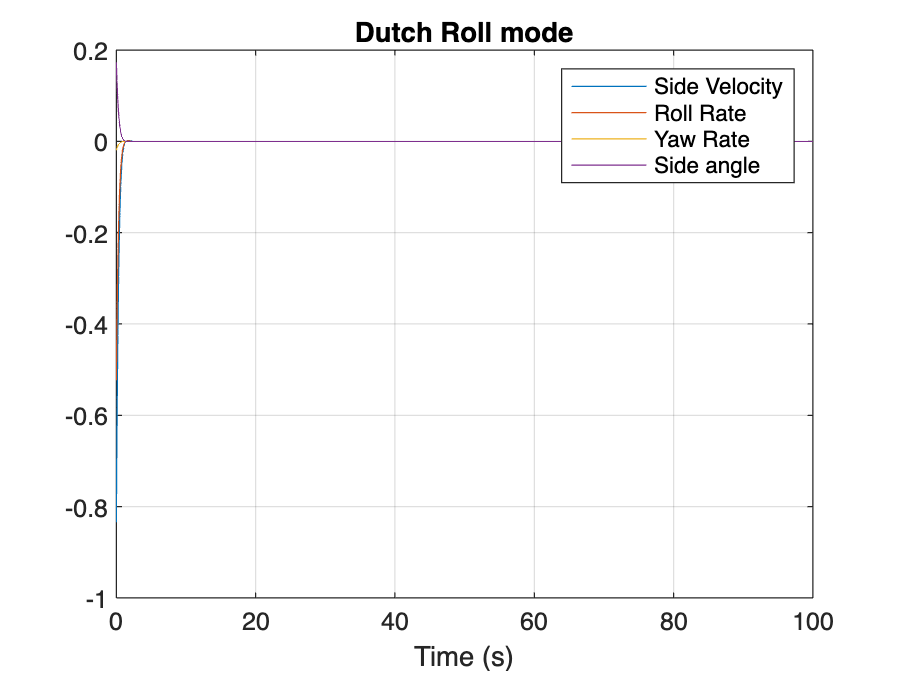


figure
plot(t, f11, t, f21, t, f31, t, f41)
title('Dutch Roll mode')
xlabel('Time (s)')
legend('Side Velocity', 'Roll Rate', 'Yaw Rate', 'Side angle')
grid on

### 6) Transfert functions of each variable

s = sym('s')

$$s = s$$

I2 = eye(4,4)

I2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


####         Lateral Matrix A Aileron

adj_A_lat = adjoint(s*I2-A_lat)

det3 = vpa(det(s*I2-A_lat))

$$det3 = s^{4}+3.6478721694668948538620156796242\,s^{3}+5.0204663160767241923292132314087\,s^{2}+9.4387884041824000584321421700273\,s+0.0090311469869933082759172134564888$$

M3 = vpa(adj_A_lat*[Ydelta_a; Ldelta_a; Ndelta_a; 0])

$$M3 = \left(\begin{array}{c} 1.2276254844234800036056883427139\,s+0.031004339184417900922529942981512\\ 0.076422865809508896961510515666305\,s^{3}+0.052039803633711204224571286093213\,s^{2}+0.22316480037945939652956736812704\,s\\ -0.0096674338786256791083623104430033\,s^{2}-0.00093110799917406271384398228357897\,s+0.0012500003024274827571455963831745\\ 0.076422865809508896961510515666305\,s^{2}+0.052039803633711204224571286093213\,s+0.22316480037945939652956736812704 \end{array}\right)$$

%v(s)
v = tf(sym2poly(M3(1)), poly(A_lat))


v =
 
                  1.228 s + 0.031
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


%p(s)
p = tf(sym2poly(M3(2)), poly(A_lat))


p =
 
       0.07642 s^3 + 0.05204 s^2 + 0.2232 s
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


%r(s)
r = tf(sym2poly(M3(3)), poly(A_lat))


r =
 
       -0.009667 s^2 - 0.0009311 s + 0.00125
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


%phi(s)
phi = tf(sym2poly(M3(4)), poly(A_lat))


phi =
 
         0.07642 s^2 + 0.05204 s + 0.2232
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


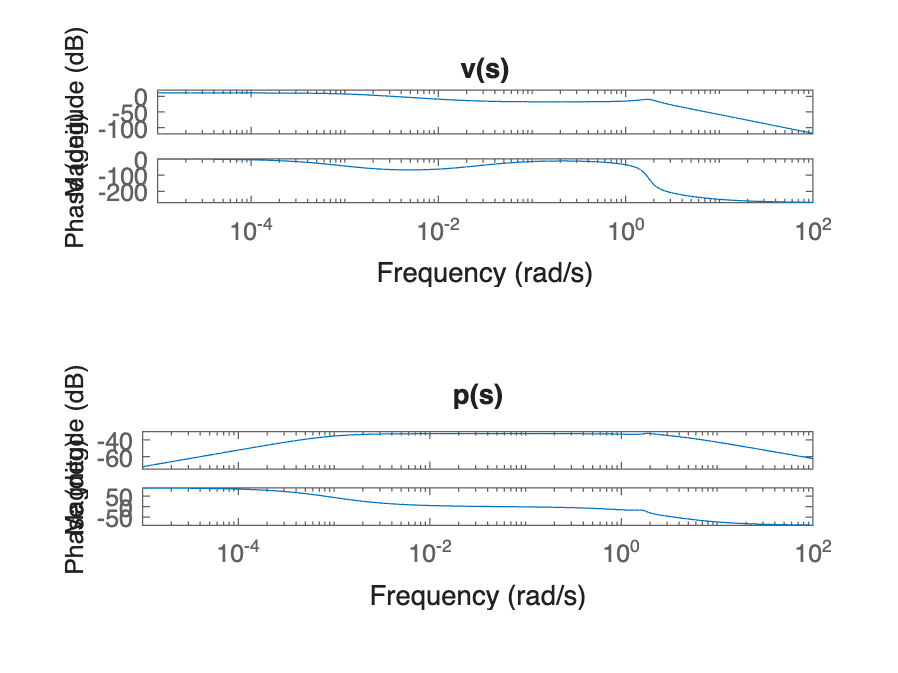


figure('Name', 'Bode Lateral Transfert Functions')
subplot(2,1,1)
bode(v)
title('v(s)')
subplot(2,1,2)
bode(p)
title('p(s)')

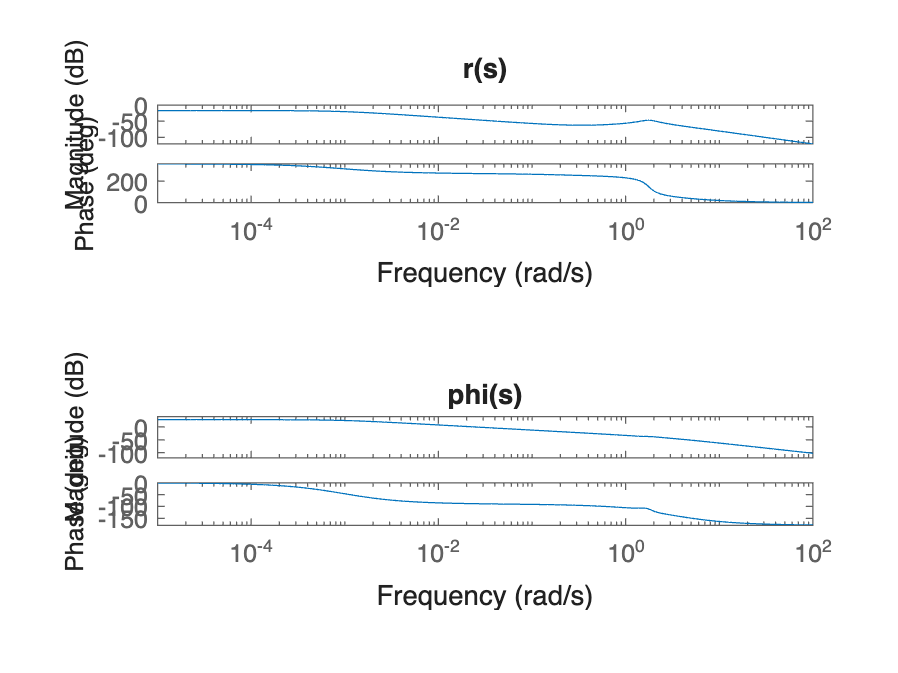


figure('Name', 'Bode Lateral Transfert Functions')
subplot(2,1,1)
bode(r)
title('r(s)')
subplot(2,1,2)
bode(phi)
title('phi(s)')

####         Lateral Matrix A Rudder

M4 = vpa(adj_A_lat*[Ydelta_r; Ldelta_r; Ndelta_r; 0])

$$M4 = \left(\begin{array}{c} 0.061992078501350390828950054356028\,s^{3}-2.8137827664462944419927124784174\,s^{2}-9.0363365297848298491100935174929\,s+0.00724069172707443756317489874655\\ -0.0091707438971410665945471762938723\,s^{3}+0.0065900189902880826989172611154931\,s^{2}+0.11884931638243342206089306257534\,s\\ 0.024970792157701513641621104966362\,s^{3}+0.079112823997560488699474063124748\,s^{2}+0.011957094764975091434086370808893\,s+0.00067766105504373084458677076797966\\ -0.0091707438971410665945471762938723\,s^{2}+0.0065900189902880826989172611154931\,s+0.11884931638243342206089306257534 \end{array}\right)$$

%v(s)
v = tf(sym2poly(M4(1)), poly(A_lat))


v =
 
   0.06199 s^3 - 2.814 s^2 - 9.036 s + 0.007241
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


%p(s)
p = tf(sym2poly(M4(2)), poly(A_lat))


p =
 
      -0.009171 s^3 + 0.00659 s^2 + 0.1188 s
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


%r(s)
r = tf(sym2poly(M4(3)), poly(A_lat))


r =
 
  0.02497 s^3 + 0.07911 s^2 + 0.01196 s + 0.0006777
  -------------------------------------------------
   s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


%phi(s)
phi = tf(sym2poly(M4(4)), poly(A_lat))


phi =
 
        -0.009171 s^2 + 0.00659 s + 0.1188
  -----------------------------------------------
  s^4 + 3.648 s^3 + 5.02 s^2 + 9.439 s + 0.009031
 
Continuous-time transfer function.
Model Properties


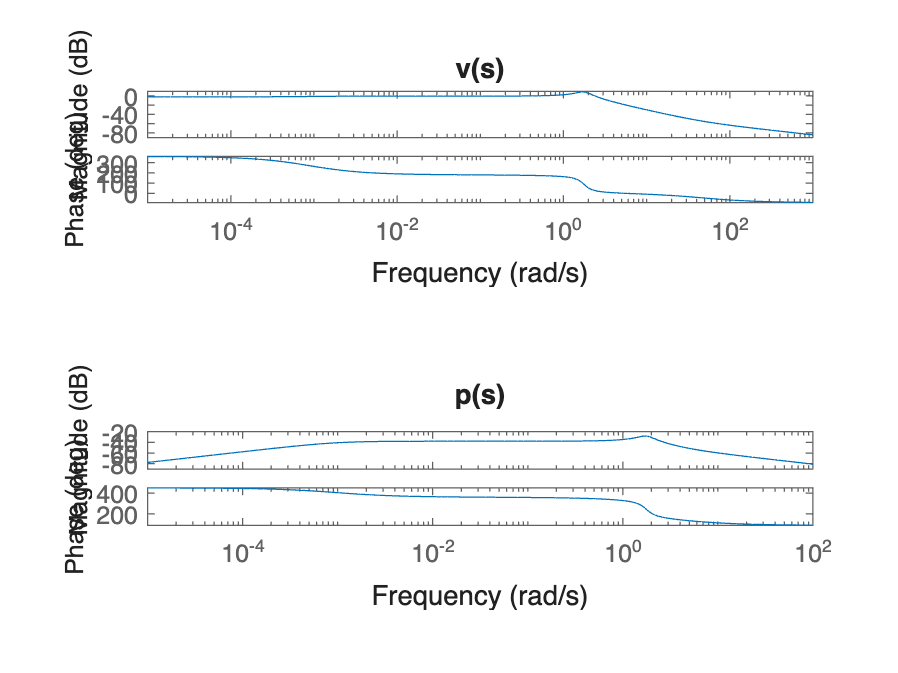


figure('Name', 'Bode Lateral Transfert Functions')
subplot(2,1,1)
bode(v)
title('v(s)')
subplot(2,1,2)
bode(p)
title('p(s)')

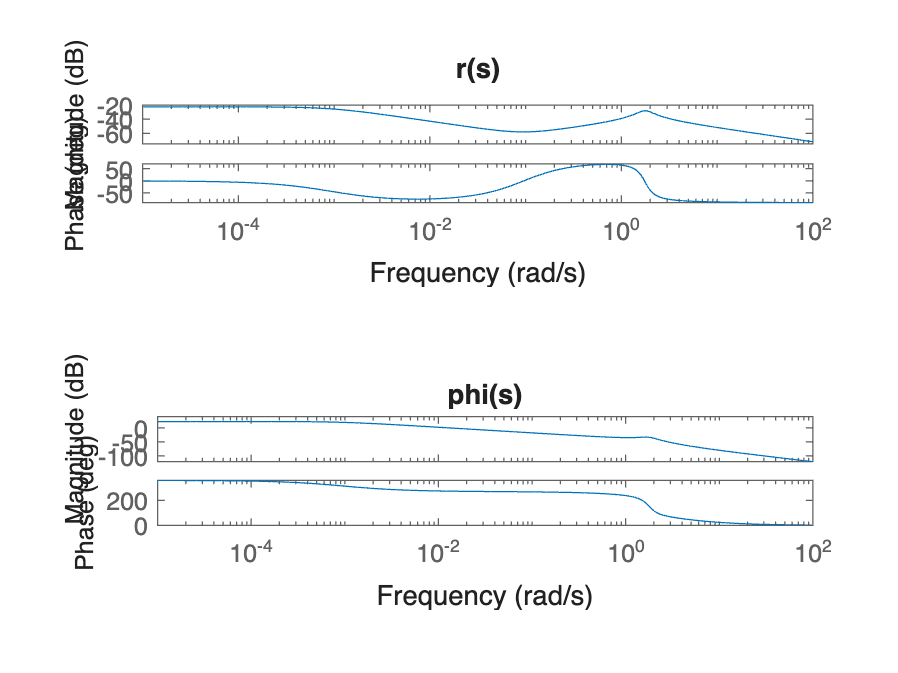


figure('Name', 'Bode Lateral Transfert Functions')
subplot(2,1,1)
bode(r)
title('r(s)')
subplot(2,1,2)
bode(phi)
title('phi(s)')